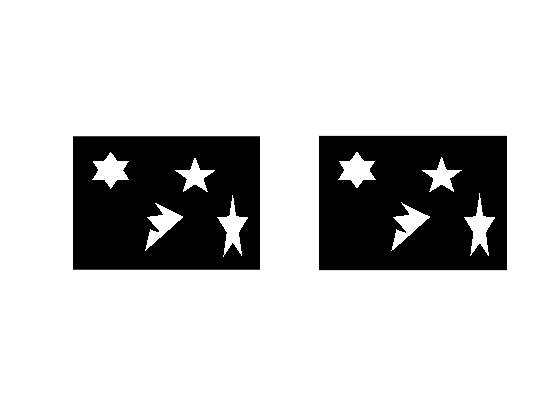

% load an image from workspace, colour or gray scale
% Image = oval_circle_bar_square_oval_holes;
% Image = four_objects;
Image = imread('four_objects.jpg');
ImageGray = rgb2gray( Image );
subplot(1,2,1); imshow( Image );
subplot(1,2,2); imshow( ImageGray );

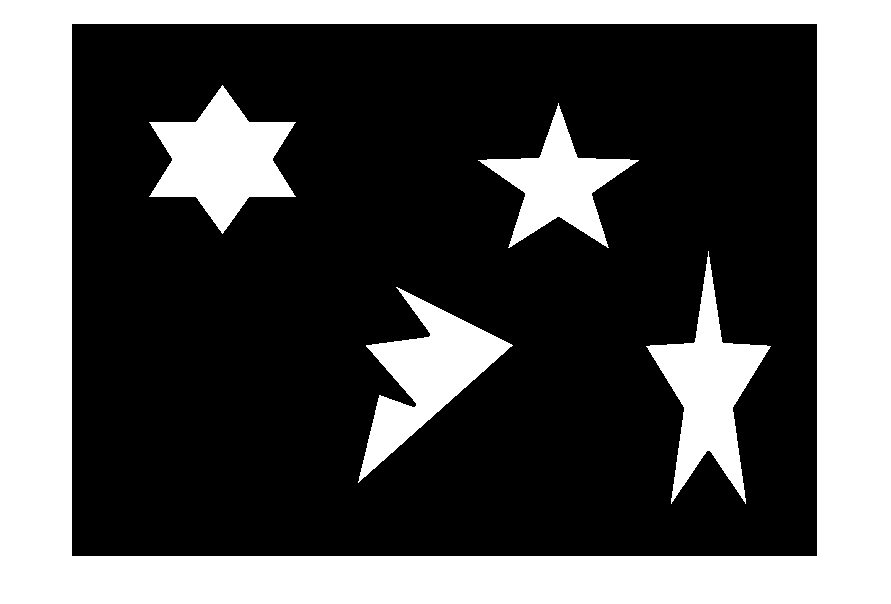

% segment gray scale version of oval_circle_bar_square_oval_holes
% Threshold image - global threshold
BW = imbinarize(ImageGray);

% Create masked image.
maskedImage = ImageGray;
maskedImage(~BW) = 0;
figure; imshow( BW );


% get all region properties (uncomment next line and edit for specific properties)
% properties = regionprops(BW, {'Area', 'BoundingBox','ConvexArea', 'Eccentricity', 'EquivDiameter', 'EulerNumber', 'Extent', 'FilledArea', 'MajorAxisLength', 'MinorAxisLength', 'Orientation', 'Perimeter', 'Solidity'});
properties = regionprops(BW, 'all');
% or output as a table
% properties_table = regionprops('table',BW, {'Area', 'ConvexArea', 'Eccentricity', 'EquivDiameter', 'EulerNumber', 'Extent', 'FilledArea', 'MajorAxisLength', 'MinorAxisLength', 'Orientation', 'Perimeter', 'Solidity'})
properties_table = regionprops('table', BW, 'all');
properties_table

properties_table = 4×23 table
    Area         Centroid                  BoundingBox                         SubarrayIdx               MajorAxisLength    MinorAxisLength    Eccentricity    Orientation     ConvexHull         ConvexImage       ConvexArea          Image             FilledImage       FilledArea    EulerNumber      Extrema       EquivDiameter    Solidity    Extent       PixelIdxList         PixelList        Perimeter    PerimeterOld
    _____    ________________    ________________________________    ________________________________

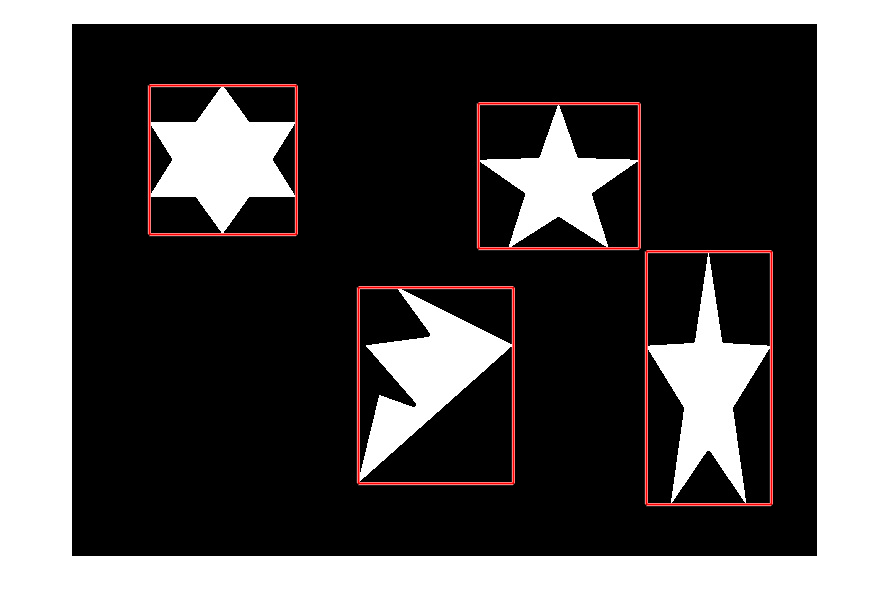

% Display BoundingBox
figure; 
imshow( ImageGray );
hold on
[nregions, ~] = size(properties);
for i = 1:nregions
    mask = false(size(BW));
    x = round( properties(i).BoundingBox(1) );
    y = round( properties(i).BoundingBox(2) );
    xmax = x + round( properties(i).BoundingBox(3) );
    ymax = y + round( properties(i).BoundingBox(4) );
    mask(y: ymax, x: xmax) = true;
    visboundaries(mask,'Color','r'); 
end
hold off;

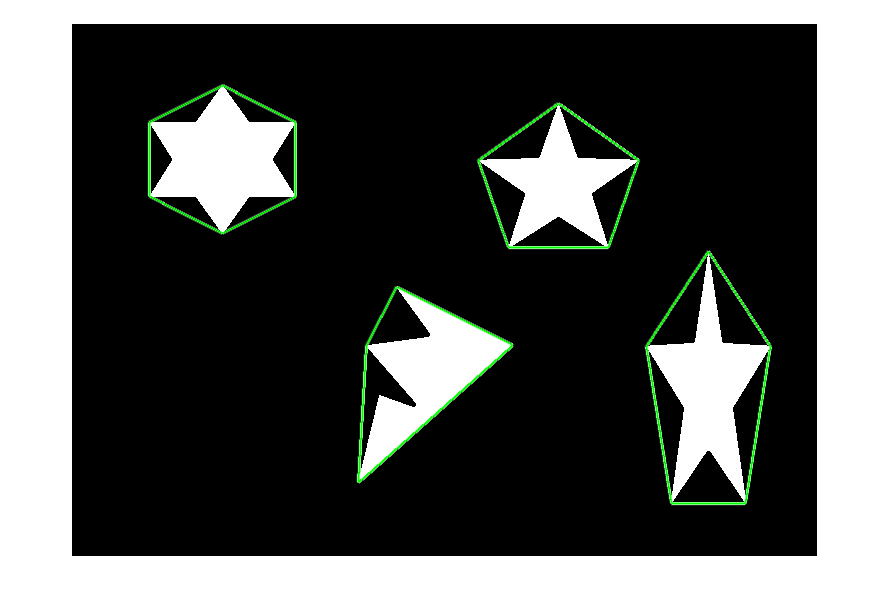

% Display ConvexHull
% https://uk.mathworks.com/help/matlab/ref/convhull.html?searchHighlight=Convex%20Hull&s_tid=doc_srchtitle
figure; 
imshow( ImageGray );
hold on
CH = bwconvhull(BW,'objects');
visboundaries(CH,'Color','g');
hold off;

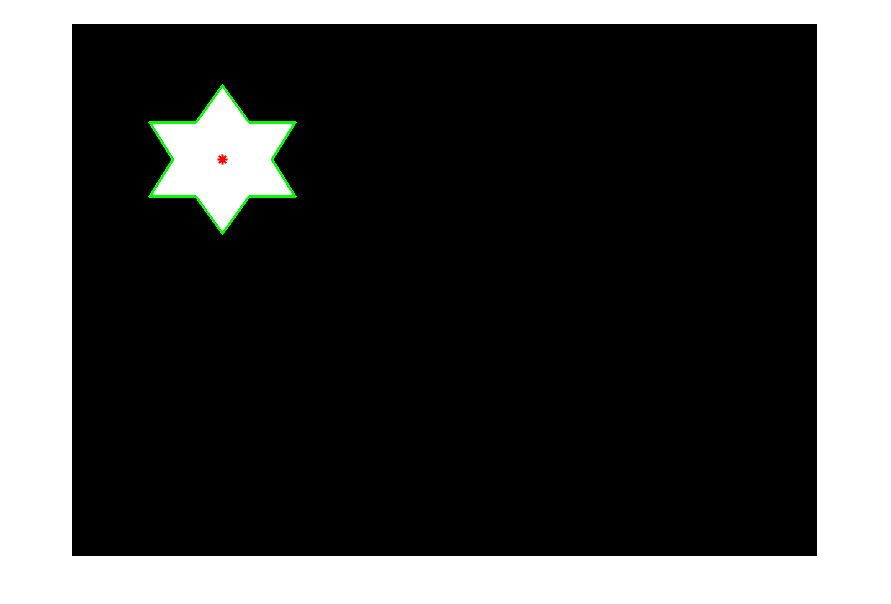

meanarc = 61.7778

minarc = 45.7852

maxarc = 81.8547

rationmin = 0.7411

rationmax = 1.3250

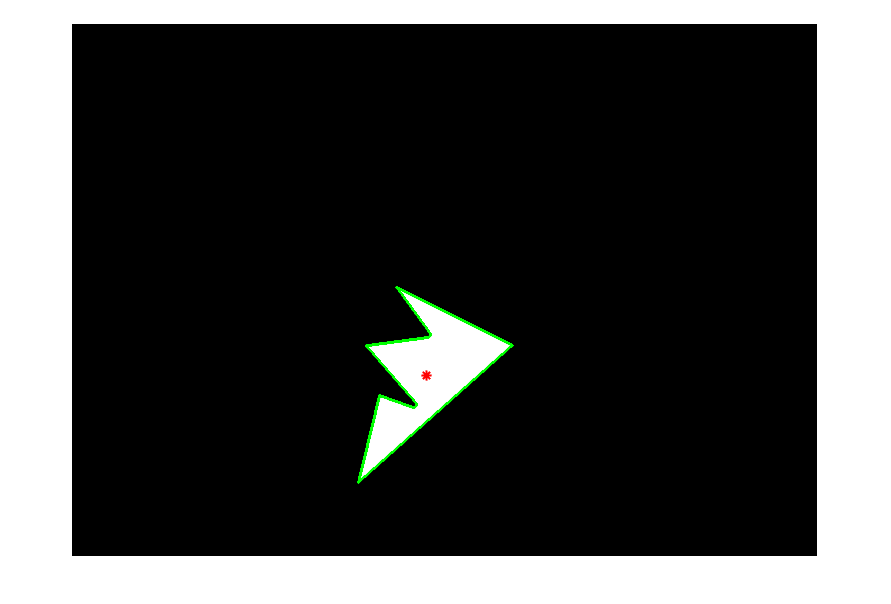

meanarc = 64.4632

minarc = 25.9683

maxarc = 127.1821

rationmin = 0.4028

rationmax = 1.9729

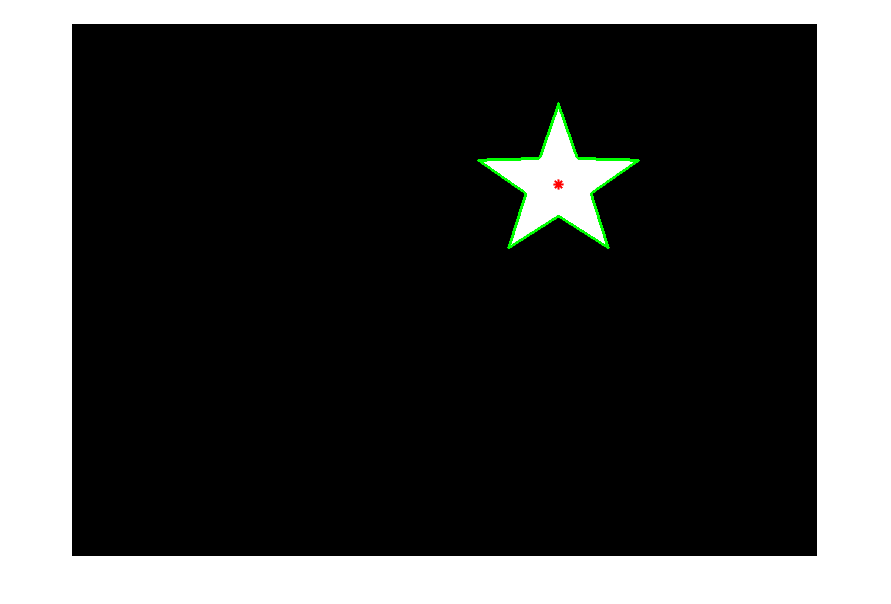

meanarc = 55.6600

minarc = 32.0709

maxarc = 83.5272

rationmin = 0.5762

rationmax = 1.5007

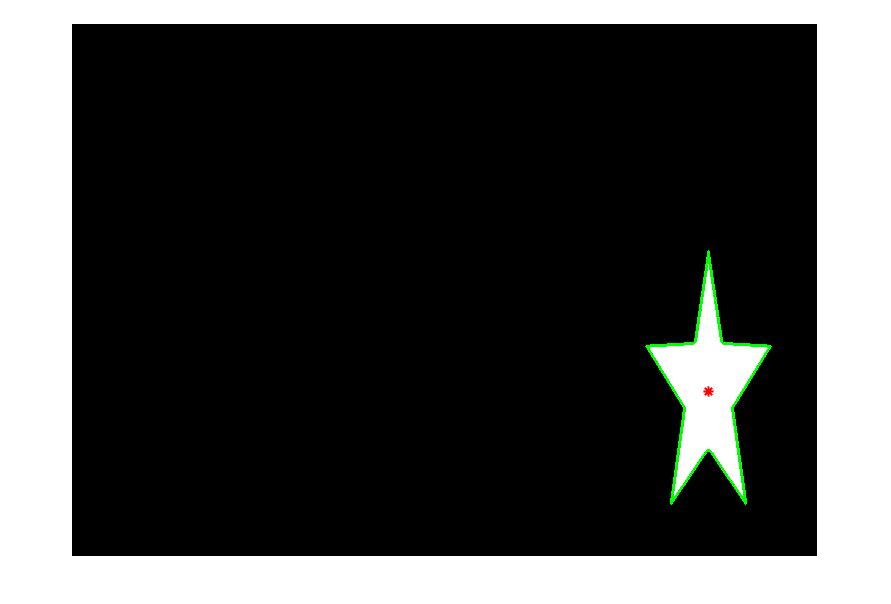

meanarc = 73.9329

minarc = 28.7352

maxarc = 139.7617

rationmin = 0.3887

rationmax = 1.8904

% Average Internal Arc Length
% Maximal and Minimal Internal Arc Ratio
[height,width,~] = size(Image);
maskall = false(size(BW));
maxl = sqrt(height^2 + width^2);
for i = 1:nregions
    cogx = properties(i).Centroid(1);
    cogy = properties(i).Centroid(2);
    arcsum = 0;
    arcn = 0;
    minarc = maxl;
    maxarc = 0;
    mask = false(size(BW));
    [pixels, ~] = size(properties(i).PixelList);
    for j = 1:pixels
        x = properties(i).PixelList(j,1);
        y = properties(i).PixelList(j,2);
        mask(y, x) = true;
    end
    [rows, columns] = find(bwperim(mask));
    figure; imshow(mask); %check that correct region produced
    hold on
%    plot(cogx, cogy,'Color','r','MarkerSize', 50);
    plot(cogx, cogy,'r*','LineWidth',2,'MarkerSize', 10);
    [pcount, ~] = size( columns );
    for j = 1:pcount
        x = columns( j );
        y = rows( j );
        plot(x, y,'g*','MarkerSize',2);
        % plot([cogx, cogy], [x,y],'Color','g');
        arc = sqrt( (cogx-x)^2 + (cogy-y)^2 );
        arcsum = arcsum + arc;
        if (arc < minarc)
            minarc = arc;    
        end
        if (arc > maxarc)
            maxarc = arc;    
        end
    end
    hold off;
    maskall = maskall + mask;
    meanarc = arcsum/pcount
    minarc
    maxarc
    rationmin = minarc/meanarc
    rationmax = maxarc/meanarc
end

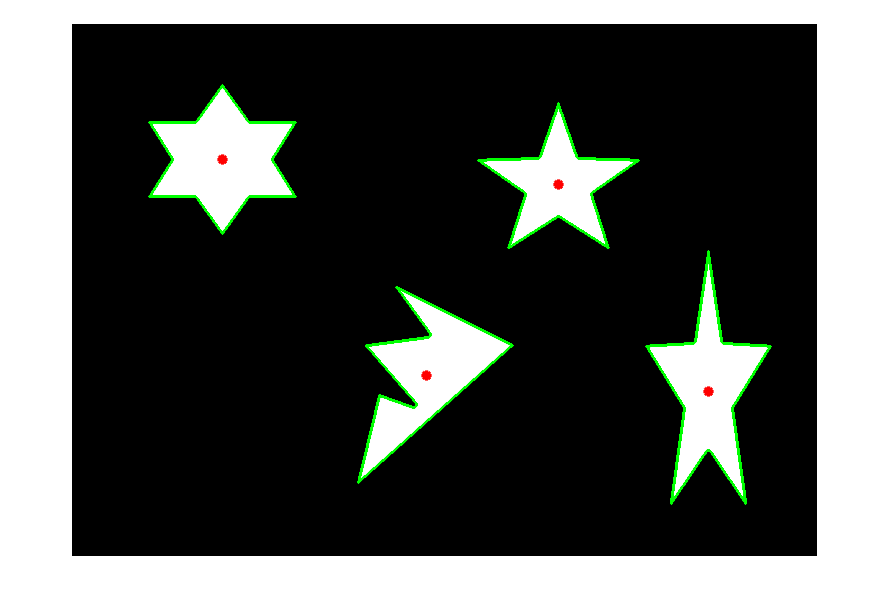

% generate image with all features, boundaries and CoGs
figure; imshow(maskall); hold on
for i = 1:nregions
    cogx = properties(i).Centroid(1);
    cogy = properties(i).Centroid(2);
    plot(cogx, cogy,'r*','LineWidth',3,'MarkerSize', 10);
    [rows, columns] = find(bwperim(maskall));
    [pcount, ~] = size( columns );
    for j = 1:pcount
        x = columns( j );
        y = rows( j );
        plot(x, y,'g*','MarkerSize',2);
    end
end
hold off;

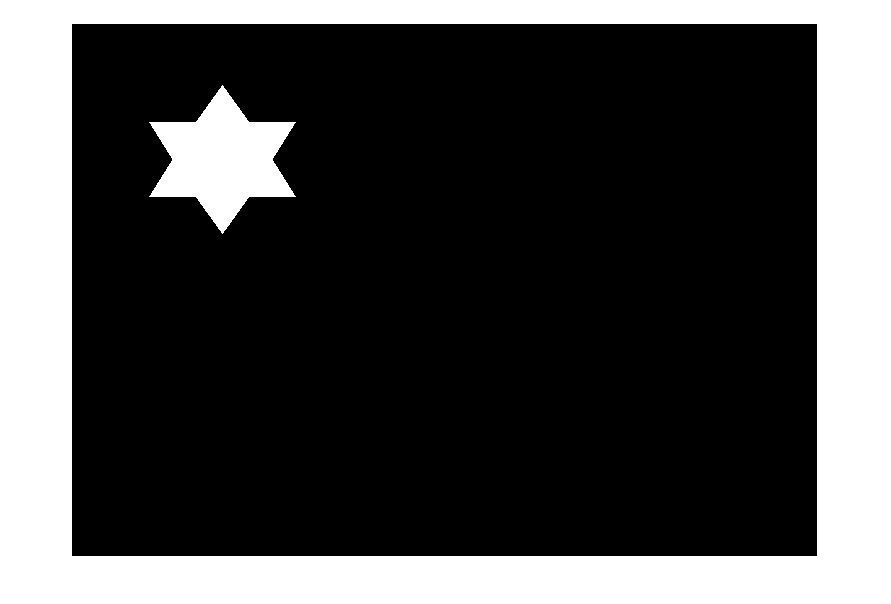

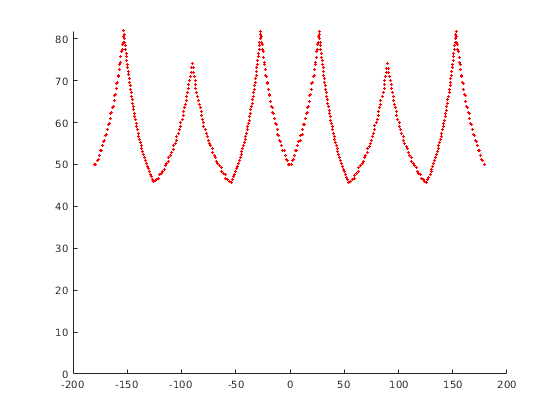

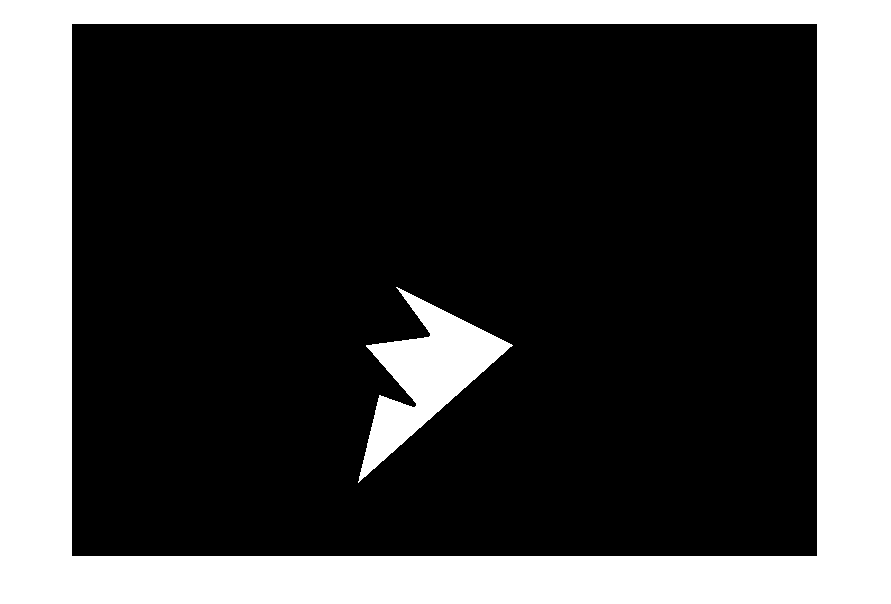

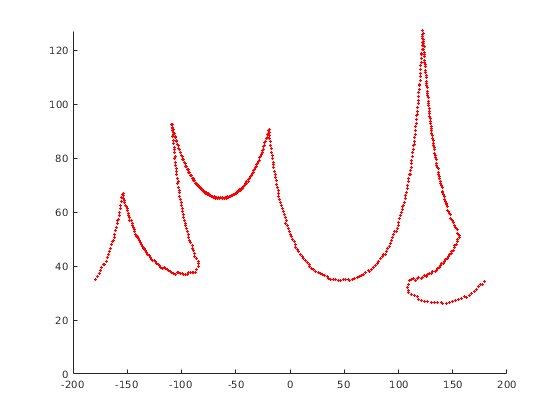

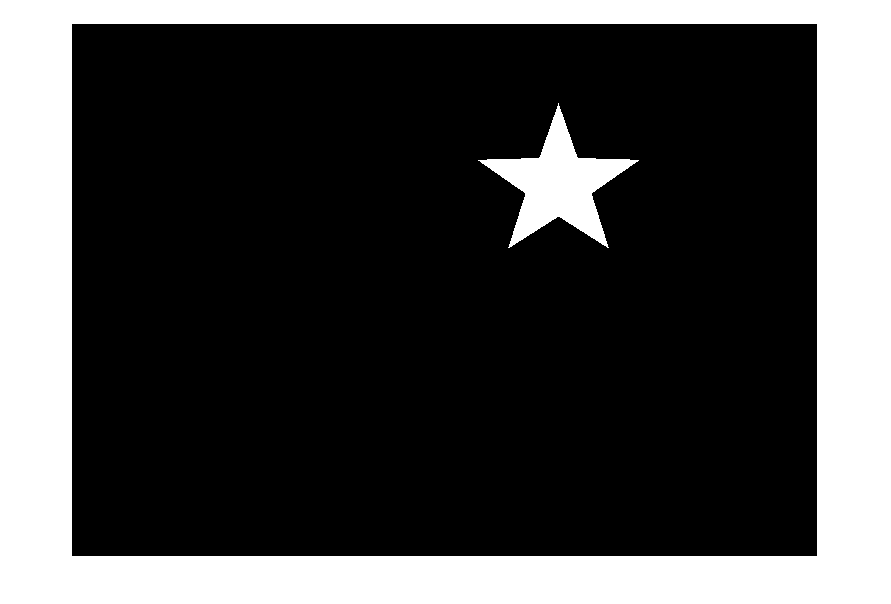

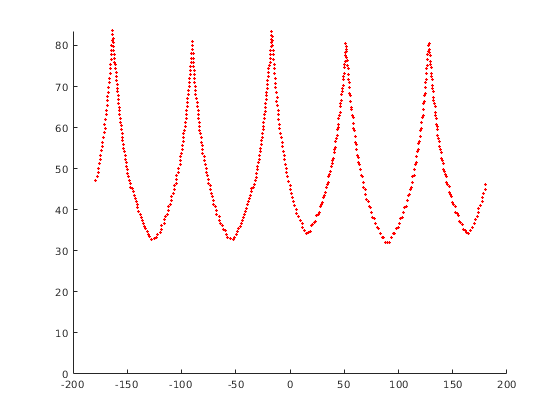

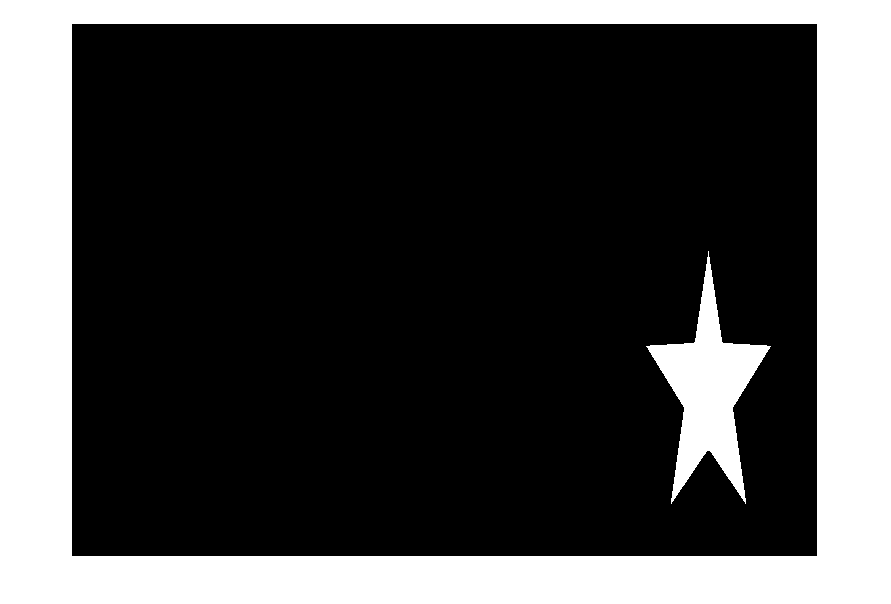

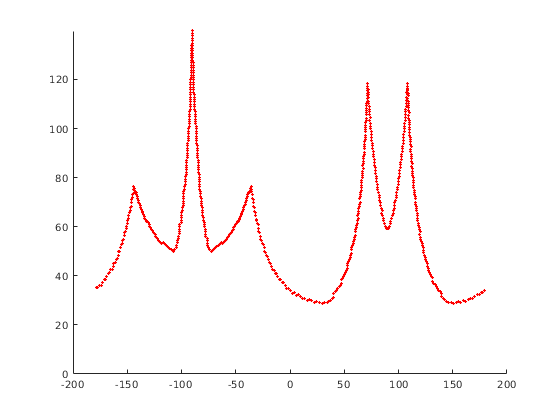

% (phi s) plot
% https://uk.mathworks.com/help/matlab/ref/atan2.html
for i = 1:nregions
    cogx = properties(i).Centroid(1);
    cogy = properties(i).Centroid(2);
    [pixels, ~] = size(properties(i).PixelList);
    mask = false(size(BW));
    for j = 1:pixels
        x = properties(i).PixelList(j,1);
        y = properties(i).PixelList(j,2);
        mask(y, x) = true;
    end
    [rows, columns] = find(bwperim(mask));
    [pcount, ~] = size( columns );
    figure; imshow(mask);
    figure; hold on
    for j = 1:pcount
        x = columns( j );
        y = rows( j );
        arc = sqrt( (cogx-x)^2 + (cogy-y)^2 );
        angle = atan2((y-cogy), (x-cogx))*180/pi;
        plot(angle, arc,'r*','MarkerSize',2)
        ylim([0 inf])
    end
   hold off;
end

% Reduced property tables for Bounding Box and Convex Hull
properties = regionprops(BW, {'Area', 'BoundingBox','ConvexArea', 'Eccentricity', 'EquivDiameter', 'EulerNumber', 'Extent', 'FilledArea', 'MajorAxisLength', 'MinorAxisLength', 'Orientation', 'Perimeter', 'Solidity'});
% or output as a table
properties_table = regionprops('table',BW, {'Area', 'ConvexArea', 'Eccentricity', 'EquivDiameter', 'EulerNumber', 'Extent', 'FilledArea', 'MajorAxisLength', 'MinorAxisLength', 'Orientation', 'Perimeter', 'Solidity'})

properties_table = 4×12 table
    Area     MajorAxisLength    MinorAxisLength    Eccentricity    Orientation    ConvexArea    FilledArea    EulerNumber    EquivDiameter    Solidity    Extent     Perimeter
    _____    _______________    _______________    ____________    ___________    __________    __________    ___________    _____________    ________    _______    _________

    11253        133.06             118.37           0.45675        0.015111        16427         11253            1             119.7        0.68503     0.51377     537.76  
    10654        186.73             